# Differential Drive Robot

Optimize the drive motors of the robot according to the provided waypoints and its conception.

Based on 

## Problem Definition

### Robot Kinematic Parameters

robot.R = 0.08;   %Wheel radius (m)
robot.M = 2;      %Robot Mass (kg)
robot.d = 0;      %Mass center/wheel excentricity (m)
robot.L = 0.15;   %Robot Semi-Length (m)
robot.J = 1/2*M*L^2;    %Robot inertial moment (kg.m^2)

### Robot Electrical Parameters

robot.N = 1;      %Motor Gear Ratio ()
robot.Ra = 1.13;  %Motor Armature Resistance (Ohms)
robot.La = 4.8e-3;  %Motor Armature Inductance (H)
robot.Kt = 1.85/3.5;  %Motor Torque Constant (N.m/A)
robot.Kb = Kt*2*pi/60;  %Motor Back EMF Constant (V.s/rad)

### Robot Initial States

The robot position is computed in absolute according to the frame at the South/West of the "Table" (considered as the authorized area)

xMax = [340 210]*1e-2; %Table Length(X)/Width(Y) (m)
x0 = [20 60]*1e-2;  %Starting Position (m)
theta0 = deg2rad(30);        %Starting Heading (rad) trigo from East

### Requested Waypoints

wp = [100 70 deg2rad(50);  %Waypoints in the frame X/Y (m) and direction (rad)
      150 40 deg2rad(-45)];
wp(:,1:2) = wp(:,1:2)*1e-2;

## Compute Optimization Problem

soln = diffDriveOptim(robot,xMax,x0,theta0,wp);

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
Running OptimTraj, iteration 1
  -> Transcription via trapezoid method, nGrid = 12

                                                               Norm of First-order
 Iter  Func-count            Fval Feasibility  Step Length        step  optimality
    0         111    3.524590e+00   1.783e+02                            1.000e+00
    1         222    1.527764e+00   4.388e+01    1.000e+00   1.588e+01   1.009e+03
    2         333    9.957359e-01   1.002e+01    1.000e+00   1.078e+01   3.216e+03
    3         444    9.957359e-01   5.900e-01    1.000e+00   3.454e+00   1.413e+04
    4         471    9.957359e-01   5.900e-01    6.571e-05   2.064e-06   1.413e+04

Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the 

## Visualisation

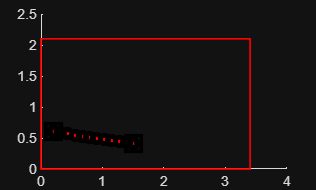

figure(1); clf; hold on;

rectangle('Position',[0,0,xMax],'EdgeColor','r','LineWidth',1);

soln = soln{1};

t = linspace(soln.grid.time(1), soln.grid.time(end), 150);
z = soln.interp.state(t);
x = z(4,:);
y = z(5,:);
th = z(3,:);
u = soln.interp.control(t);

tGrid = soln.grid.time;
xGrid = soln.grid.state(4,:);
yGrid = soln.grid.state(5,:);
thGrid = soln.grid.state(3,:);
uGrid = soln.grid.control;

% Plot the entire trajectory
plot(x,y,'r-','LineWidth',3);

% Plot the grid points:
plot(xGrid, yGrid, 'ko','MarkerSize',5,'LineWidth',3);

% Plot the start and end points:
plot(x([1,end]), y([1,end]),'ks','MarkerSize',12,'LineWidth',3);

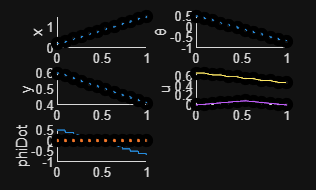


% Plot the state and control:
figure(2); clf; 

subplot(3,2,1); hold on;
plot(t,x);
plot(tGrid,xGrid,'ko','MarkerSize',5,'LineWidth',3);
ylabel('x');

subplot(3,2,3); hold on;
plot(t,y);
plot(tGrid,yGrid,'ko','MarkerSize',5,'LineWidth',3);
ylabel('y');

subplot(3,2,2); hold on;
plot(t,th);
plot(tGrid,thGrid,'ko','MarkerSize',5,'LineWidth',3);
ylabel('θ');

subplot(3,2,5); hold on;
plot(t,th);
plot(tGrid,soln.grid.state(1,:),tGrid,soln.grid.state(2,:),'ko','MarkerSize',5,'LineWidth',3);
ylabel('phiDot');

subplot(3,2,4); hold on;
plot(tGrid,uGrid,'ko','MarkerSize',5,'LineWidth',3);
plot(t,u);
ylabel('u');